# Transducer Design

Transducer 1

% Define common properties
transducer_info = struct();
transducer_info.Frequency = 4e4;    % 40kHz (operating frequency of transducer)
transducer_info.Pressure = 1;       % How to set this parameter?
transducer_info.Type = 'circle';
transducer_info.Radius = 5e-3;      
transducer_info.rotate = [0, 0, 0];
transducer_info.medium = 'air';


% Positions and phases for the transducers (rectangular)
positions = [];
for k = 1:16
    positions(k) = 0.005 + 0.01 * (k-1);
end
% PFC_PhaseCalculate(target[x,y], array, focal point z(m))
phases = PFC_PhaseCalculate([0.08, 0.08], [16,16], 0.5)

phases =          0    1.0137    1.8848    2.6122    3.1952    3.6330    3.9252    4.0713    4.0713    3.9252    3.6330    3.1952    2.6122    1.8848    1.0137         0
    1.0137    2.0302    2.9036    3.6330    4.2176    4.6566    4.9496    5.0961    5.0961    4.9496    4.6566    4.2176    3.6330    2.9036    2.0302    1.0137
    1.8848    2.9036    3.7791    4.5102    5.0961    5.5362    5.8298    5.9768    5.9768    5.8298    5.5362    5.0961    4.5102    3.7791    2.9036    1.8848
    2.6122    3.6330    4.5102    5.2427    5.8298    6.2708    6.5650    6.7122    6.7122    6.5650    6.2708    5.8298    5.2427    4.5102    3.6330    2.6122
    3.1952    4.2176    5.0961    5.8298    6.4179    6.8595    7.1542    7.3016    7.3016    7.1542    6.8595    6.4179    5.8298    5.0961    4.2176    3.1952
    3.6330    4.6566    5.5362    6.2708    6.8595    7.3016    7.5967    7.7443    7.7443    7.5967    7.3016    6.8595    6.2708    5.5362    4.6566    3.6330
    3.9252    4.9496    5

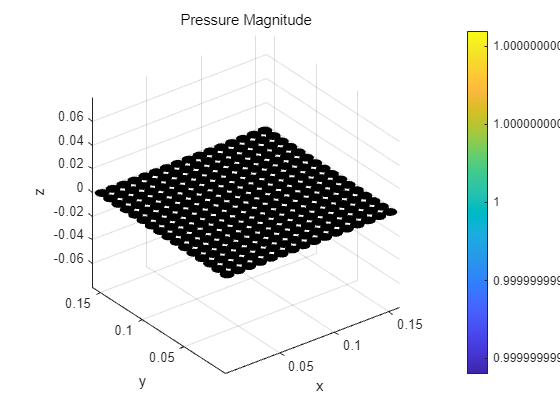

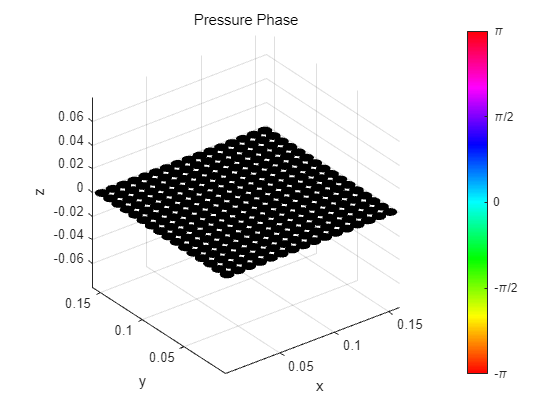

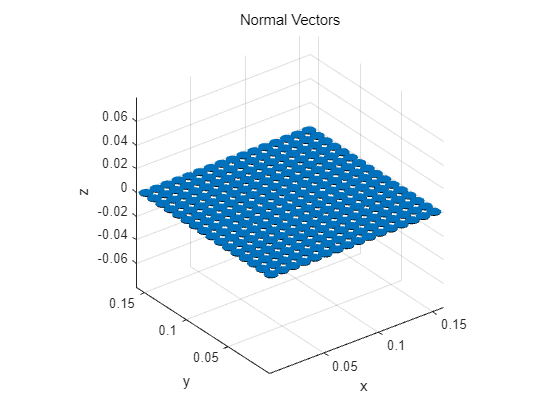


% Counter for linear indexing into transducer_object
index = 1;

% Populate the transducer objects
for i = 1:16
    for j = 1:16
        % Update position and phase
        transducer_info.position = [positions(j), positions(i), 0];
        transducer_info.Phase = phases(i, j);
        transducer_object(index) = PFC_Make3DTransducer(transducer_info);
        
        % Increment index for next transducer
        index = index + 1;
    end
end

% Draw all transducers in 3D once
PFC_DrawTransducer3D(transducer_object, '-');

## Frequency Domain

input_source.Type = 'frequency';
input_source.reading_list = 1e6; % [Hz]

## Simulation Space

reading_pos_x = 0 : 0.5e-3 : 160e-3;          % Simulation Area
reading_pos_y = 0 : 0.5e-3 : 160e-3;          % Simulation Area
reading_pos_z = 300e-3 : 1e-3 : 600e-3;          % Simulation Area

## Run Frequency Domain Simulation

% xz plane
[Pressure_dxyz, ~] = ...
    PFC_CalculatePressureField(...
    transducer_object, input_source,...                 % tx setting
    reading_pos_x, 0.08, reading_pos_z);

Started at 2024-05-03 00:01:19
Finished at 2024-05-03 00:04:46
Progressed time : 00:03:27



Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

figure;imagesc(reading_pos_z.*1e3, reading_pos_x.*1e3, Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top');
title('View of XZ plane at y = 80mm');
colorbar;
M1 = max(Pressure_dxyz_i,[],"all")

M1 = 1.4760

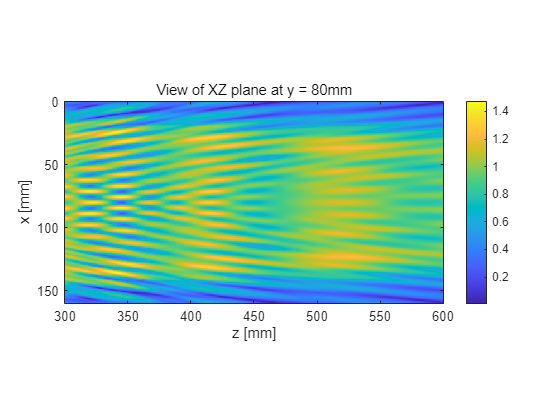

xlabel('z [mm]');
ylabel('x [mm]');




% xy plane
[Pressure_dxyz, ~] = ...
    PFC_CalculatePressureField(...
    transducer_object, input_source,...                 % tx setting
    reading_pos_x, reading_pos_y, 0.5);

Started at 2024-05-03 00:04:47
Finished at 2024-05-03 00:08:12
Progressed time : 00:03:25


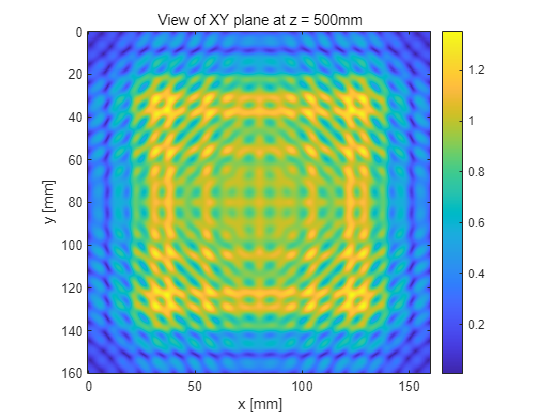


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

figure;imagesc(reading_pos_x.*1e3, reading_pos_y.*1e3, Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top');
title('View of XY plane at z = 500mm');
colorbar;
xlabel('x [mm]');
ylabel('y [mm]');

M2 = max(Pressure_dxyz_i,[],"all")

M2 = 1.3537